# Example 6.3: Sparse PCA Estimation for Gibbs Reactor

Note: this script reproduces Example 6.3 (Section 6.1.2) of **Statistics for Chemical Engineers**: sparse PCA to identify which input variables carry redundant information. Victor Z UW-Madison, 2019 sparse PCA estimation for Gibbs reactor this uses the sparsePCA package: [https://github.com/tbuehler/sparsePCA](https://github.com/tbuehler/sparsePCA)

clc; clear all; close all hidden;
format bank
addpath('./Support/SparsePCA');

## Data

generate dataset get data (pressure, conversion, flow co, flow h2, flow ch3oh)

load ('./Data/gibbs_covariance.dat')
datat=gibbs_covariance;
% get temperature data
load ('./Data/gibbs_lowtemp_class.dat')
datan=gibbs_lowtemp_class;
% join data (pressure, conversion, flow co, flow h2, flow ch3oh, temperature)
data=[datat datan(:,1)];

% perturb data with noise
rng(1); % For reproducibility 
[S,n]=size(data);
data(:,2)=data(:,2)+normrnd(0,0.05,S,1);

## Sparse PCA and estimation

construct input-outdata matrices

Y=data(:,2);
X=data(:,[1 3 4 5 6]);
[S,n]=size(X);
% join data (ones, pressure, flow co, flow h2, flow ch3oh, temperature)
X=[ones(S,1) X]; % add ones to introduce bias parameter
[S,n]=size(X);

## apply PCA estimation

% form kernel matrix and compute eigenvectors and eigenvalues
Sigma=X'*X;
[W,lam]=eigs(Sigma);
lam=diag(lam);

% eliminate small eigenvalues
n1=3;
W1=W(:,1:n1);
L1=diag(lam(1:n1));

% project input data
T1=X*W1;

% estimate parameters
gamma=inv(T1'*T1)*T1'*Y

gamma =           0.00
          0.00
          0.00


thetan=W1*gamma

thetan =           0.00
          0.00
         -0.00
         -0.00
          0.00
          0.00


Yhatn=X*thetan;
en=Yhatn-Y;
SSE=mean(en.^2)

SSE =           0.00

sig2=var(en);
Covthetan=sig2*(W1*inv(L1)*W1')

Covthetan =           0.00         -0.00         -0.00         -0.00          0.00          0.00
         -0.00          0.00          0.00          0.00         -0.00         -0.00
         -0.00          0.00          0.00          0.00         -0.00         -0.00
         -0.00          0.00          0.00          0.00         -0.00         -0.00
          0.00         -0.00         -0.00         -0.00          0.00          0.00
          0.00         -0.00         -0.00         -0.00          0.00          0.00


diag(Covthetan)'

ans =           0.00          0.00          0.00          0.00          0.00          0.00


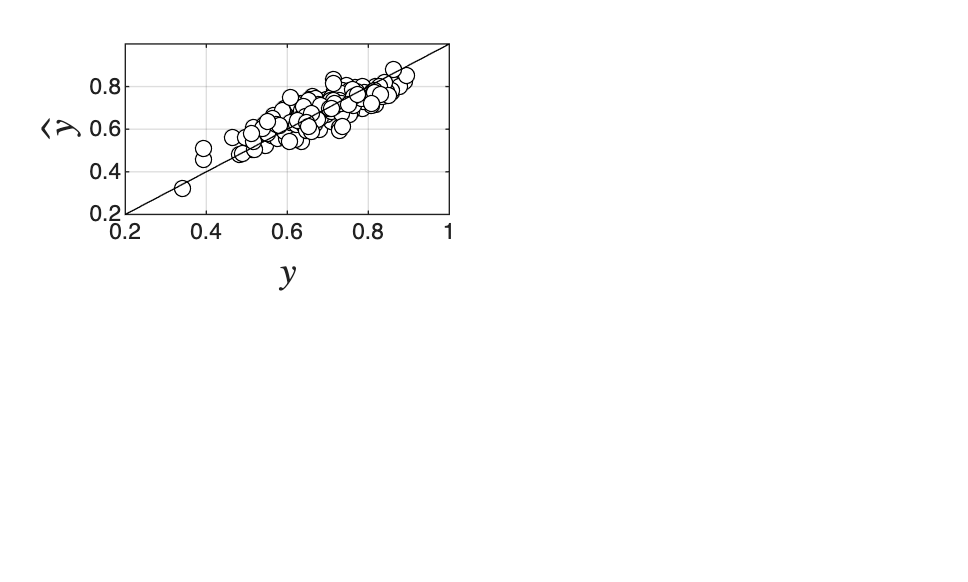


% compare predictions and observations
figure(1)
subplot(2,2,1)
xx=linspace(0,1);
plot(Y,Yhatn,'blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0.2 1 0.2 1])

## now apply sparse PCA estimation

% get dense components
card=6; %number of nonzero components in eigenvectors
num_comp=6; %number of principal components
Wdense = sparsePCA(X, card, num_comp, 0, 1)

Finished computing principal component number 1. #nonzeros=6
Finished computing principal component number 2. #nonzeros=6
Finished computing principal component number 3. #nonzeros=6
Finished computing principal component number 4. #nonzeros=6
Finished computing principal component number 5. #nonzeros=6
Finished computing principal component number 6. #nonzeros=6


Wdense =          -0.00         -0.00         -0.00          0.00         -0.00         -0.00
         -0.19         -0.84          0.50          0.18         -0.08          0.62
         -0.04          0.23          0.38          0.04          0.17          0.44
         -0.61          0.40          0.45          0.45         -0.61         -0.45
         -0.09         -0.25         -0.45         -0.16         -0.74          0.44
         -0.76         -0.09         -0.45          0.86          0.19          0.17



card=1; %number of nonzero components in eigenvectors
num_comp=6; %number of principal components
Wsparse = sparsePCA(X, card, num_comp, 0, 1)

Finished computing principal component number 1. #nonzeros=1
Finished computing principal component number 2. #nonzeros=1
Finished computing principal component number 3. #nonzeros=1
Finished computing principal component number 4. #nonzeros=1
Finished computing principal component number 5. #nonzeros=1
Finished computing principal component number 6. #nonzeros=1


Wsparse =              0             0             0             0             0             0
             0          1.00             0             0          1.00             0
             0             0             0             0             0             0
             0             0          1.00             0             0             0
             0             0             0             0             0          1.00
          1.00             0             0          1.00             0             0



% do estimation eliminating variables recommended by sparse PCA (6,3,5). 
% corresponds to eliminating X5,X2,X4 and keeping one column (row1), X1 (row 2),X3 (row 4)
Xtmp=X;
X=X(:,[1 2 4]);

theta=inv(X'*X)*X'*Y

theta =           2.47
          0.00
         -0.00


Yhat=X*theta;
e=Yhat-Y;
SSE=mean(e.^2)

SSE =           0.00

sig2=var(e);
Covtheta=sig2*inv(X'*X)

Covtheta =           0.28         -0.00         -0.00
         -0.00          0.00          0.00
         -0.00          0.00          0.00


format long e
diag(Covtheta)

ans =      2.781923622330570e-01
     3.194136000709075e-07
     9.273912268304499e-07


lamk=eigs(X'*X)

lamk =      5.899912919243392e+07
     2.029931882500230e+05
     8.811242744497409e-03


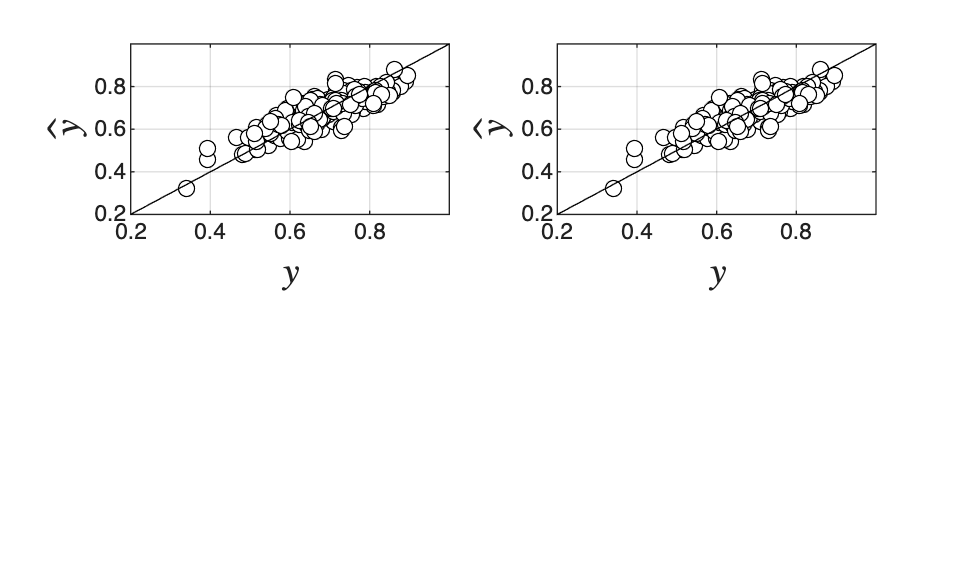


% compare predictions and observations
figure(1)
subplot(2,2,2)
xx=linspace(0,1);
plot(Y,Yhat,'blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0.2 1 0.2 1])

print -depsc ch6_gibbs_pca_fit_sparse.eps


% as a comparison, imagine we eliminate the wrong variables and instead
% keep (6,3,5)
X=Xtmp;
X=X(:,[6,3,5]);

theta=inv(X'*X)*X'*Y

theta =     -2.743076724053241e-04
     4.795429951146548e-03
     9.489195793279712e-03


Yhat=X*theta;
e=Yhat-Y;
SSE=mean(e.^2)

SSE =      6.241169820509722e-03

sig2=var(e);
Covtheta=sig2*inv(X'*X)

Covtheta =     -2.990315684455490e+05     1.743802591390223e+06     1.743802591390217e+06
     1.743802591390223e+06    -1.016898481169195e+07    -1.016898481169214e+07
     1.743802591390217e+06    -1.016898481169214e+07    -1.016898481169201e+07


format long e
diag(Covtheta)

ans =     -2.990315684455490e+05
    -1.016898481169195e+07
    -1.016898481169201e+07


lamk=eigs(X'*X)

lamk =      8.643998588298972e+07
     2.744657845747373e+04
     7.157798520562864e-10


## Note

As in the book, keeping only X5, X2, and X4 gives a poor fit and a singular kernel matrix: these input variables are the problematic ones.